
% % 五连杆机构参数 (单位：mm)
k=155^2;
% theta1 [0.1258,5.7958]rad   [7.2060,332.0767]deg
% theta4 [2.0961,5.4447]      [120.1 ,311.96  ]  
L1 = 152.5;
L2 = 160; 
L3 = 250; 
L4 = 110; 
L5 = 170;
L6 = 100;
sector = struct(...
    'r_min', 100,...   % 内半径
    'r_max', 350,...  % 外半径
    'theta_min', deg2rad(-140),...  % 起始角度（弧度）
    'theta_max', deg2rad(-40)...  % 终止角度（弧度）
    );
% 预处理：预先计算角度边界的三角函数值以加速计算
sector.sin_theta_min = sin(sector.theta_min);
sector.cos_theta_min = cos(sector.theta_min);
sector.sin_theta_max = sin(sector.theta_max);
sector.cos_theta_max = cos(sector.theta_max);
F_final = extra_Angle(L1, L2, L3, L4, L5, L6, 1, sector);

% 固定点位置
A = [-L5/2, 0]; % 基座左端固定点
E = [L5/2, 0]; % 基座右端固定点

% 模拟角度范围 (单位：弧度)
n=120;
m=20;
theta1_range_1 = linspace(0, 2*pi, n); % 连杆2角度范围
theta4_range_1 = linspace(0, 2*pi, n); % 连杆3角度范围
theta1_range = linspace(0, 2*pi, m); % 连杆2角度范围
theta4_range = linspace(0, 2*pi, m); % 连杆3角度范围
% 初始化点云数据

% 遍历角度范围，计算末端轨迹
    pointCloud_X = [];
    pointCloud_Y = [];
    valid_theta1=[];
    valid_theta2=[];
    valid_theta3=[];
    valid_theta4=[];
    phi0=[];
    l0=[];
    tic;
for i = 1:n
    theta1 = theta1_range_1(i);
    for j = 1:n
        theta4=theta4_range_1(j);
        % 计算连杆末端点 (运动学分析)
        B = A + [L1*cos(theta1), L1*sin(theta1)];
        D = E + [L4*cos(theta4), L4*sin(theta4)];
        % 使用几何关系解算其他连杆位置
        A0=2*L2*(D(1)-B(1));
        B0=2*L2*(D(2)-B(2));
        C0=L2^2+(D(1)-B(1))^2+(D(2)-B(2))^2-L3^2;
        discriminant = A0^2 + B0^2 - C0^2;
        A1=2*L3*(B(1)-D(1));
        B1=2*L3*(B(2)-D(2));
        C1=L3^2+(B(1)-D(1))^2+(B(2)-D(2))^2-L2^2;
        discriminant1 = A1^2 + B1^2 - C1^2;
        if discriminant < 0 ||discriminant1<0
            continue; % 跳过非物理解
        end
        theta2=2*atan2((B0 + sqrt(A0 ^ 2 + B0 ^ 2 - C0 ^ 2)), (A0 + C0));
        theta3=2*atan2((B1 + sqrt(A1 ^ 2 + B1 ^ 2 - C1 ^ 2)), (A1 + C1));
        C(1)=L2*cos(theta2)+B(1);
        C(2)=L2*sin(theta2)+B(2);
        cha1=((D(1)-C(1))*(E(2)-C(2))-(D(2)-C(2))*(E(1)-C(1)));
        cha2=((B(1)-A(1))*(C(2)-A(2))-(B(2)-A(2))*(C(1)-A(1)));
        if cha1<0||cha2>0||(A(2)>((D(2)-C(2))/(D(1)-C(1)))*(A(1)-C(1))+C(2))&&((D(2)-C(2))/(D(1)-C(1))<0)
            continue;
        end
        F(1)=C(1)*(L2+L6)/L2-L6*B(1)/L2;
        F(2)=C(2)*(L2+L6)/L2-L6*B(2)/L2;
        % 保存末端点
        if F(2)>0 && F(2)>C(2) && F(2)>B(2)
            pointCloud_X = [pointCloud_X; F(1)];
            pointCloud_Y = [pointCloud_Y; -F(2)];
            l0=[l0;sqrt(F(1)^2+F(2)^2)];
            phi0=[phi0;pi/2-atan2(F(2),F(1))];
            valid_theta4 = [valid_theta4; theta4];
            valid_theta1 = [valid_theta1; theta1];
            % valid_theta4 = unique([valid_theta4; theta4], 'stable'); % 记录有效的 theta4，但去除重复值
            % valid_theta3 = unique([valid_theta3; theta3], 'stable');
            % valid_theta2 = unique([valid_theta2; theta2], 'stable');
            % valid_theta1 = unique([valid_theta1; theta1], 'stable'); % 记录有效的 theta1，但去除重复值
        end
    end
end
toc;

历时 0.029176 秒。


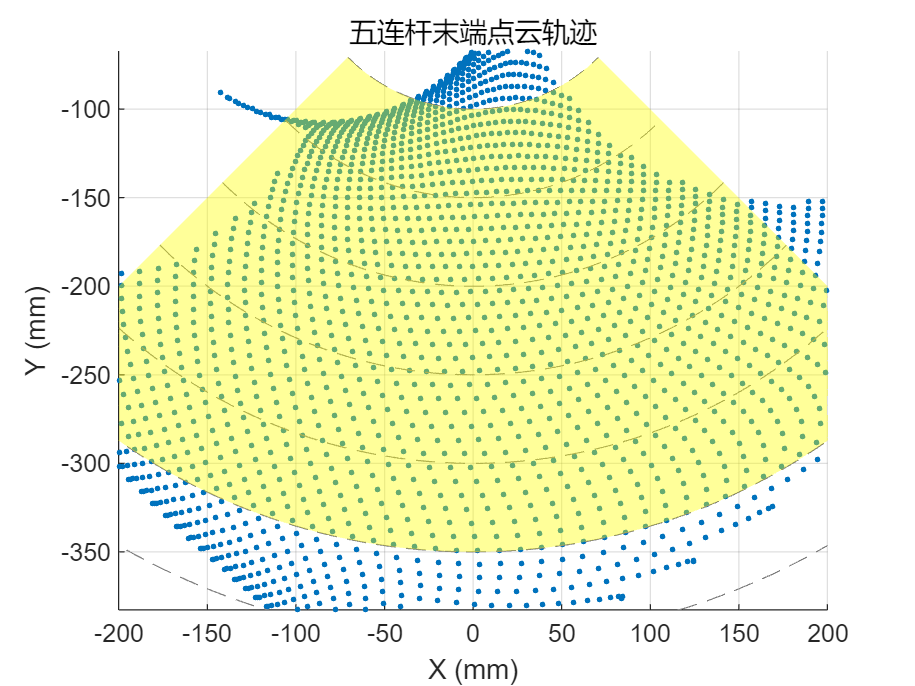

figure;
scatter(pointCloud_X, pointCloud_Y, 5, 'filled');
hold on;

% Plot the circles
for r = 100:50:450
    theta = linspace(5*pi/4, 7*pi/4, 1000); % 足够多的点使曲线平滑
    x = r * cos(theta);
    y = r * sin(theta);
    plot(x, y, 'Color', [0.5 0.5 0.5], 'LineStyle', '--'); % 灰色虚线
end

% Add the transparent fan ring
theta_fan = linspace(1.25*pi, 1.75*pi, 100); % Angular range from 1.25pi to 1.75pi
r_inner = 100; % Inner radius
r_outer = 350; % Outer radius

% Coordinates for the inner and outer edges of the fan ring
x_inner = r_inner * cos(theta_fan);
y_inner = r_inner * sin(theta_fan);
x_outer = r_outer * cos(theta_fan);
y_outer = r_outer * sin(theta_fan);

% Create the filled sector (fan ring) by connecting the inner and outer edges
fill([0, x_outer, fliplr(x_inner)], [0, y_outer, fliplr(y_inner)], 'y', 'FaceAlpha', 0.4, 'EdgeColor', 'none'); 

hold off;
xlabel('X (mm)');
ylabel('Y (mm)');
title('五连杆末端点云轨迹');
xlim([-200, 200]);
ylim([-350, -100]);
axis equal;
grid on;


% 使用alphaShape生成扫过的区域
% % 计算凸包并填充
% k = convhull(pointCloud_X, pointCloud_Y);
% figure;
% scatter(pointCloud_X, pointCloud_Y, 5, 'filled');
% hold on;
% fill(pointCloud_X(k), pointCloud_Y(k), 'r', 'FaceAlpha', 0.3);
% hold off;
% xlabel('X (mm)'); ylabel('Y (mm)');
% title('末端点F扫过的区域（凸包）');
% xlim([-200, 200]);
% ylim([-350, -100]);
% axis equal;
% grid on;

% scatter(valid_theta1, valid_theta4,3, 'filled');
% xlabel('有效的 \theta_1 (弧度)');
% ylabel('有效的 \theta_4 (弧度)');
% title('有效的 \theta_1 和 \theta_4 的散点图');
theta1_range=F_final(:,3);
theta4_range=F_final(:,4);
n1=length(F_final)

n1 = 1651

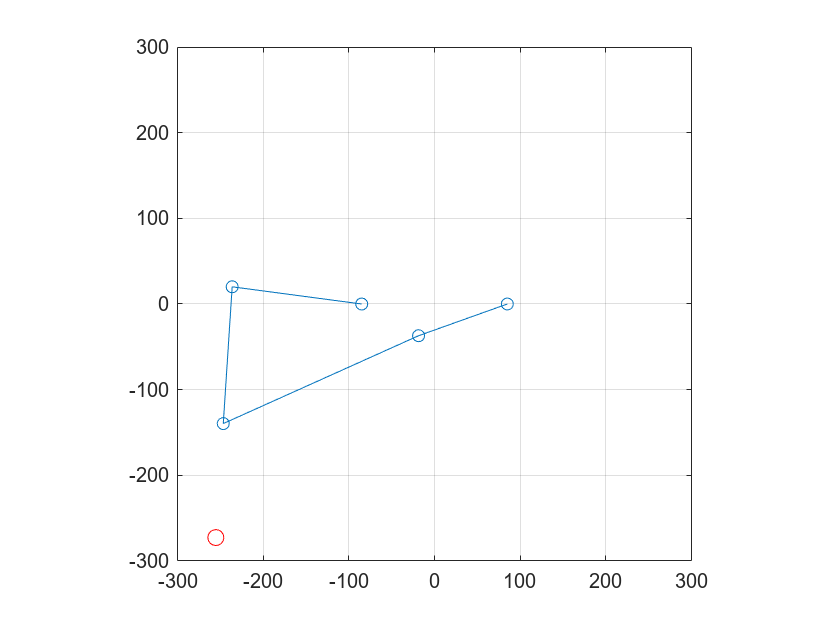

for i = 1:n1
    theta1 = theta1_range(i);
    theta4=theta4_range(i);
        % 计算连杆末端点 (运动学分析)
        B = A + [L1*cos(theta1), L1*sin(theta1)];
        D = E + [L4*cos(theta4), L4*sin(theta4)];
        % 使用几何关系解算其他连杆位置
        A0=2*L2*(D(1)-B(1));
        B0=2*L2*(D(2)-B(2));
        C0=L2^2+(D(1)-B(1))^2+(D(2)-B(2))^2-L3^2;
        discriminant = A0^2 + B0^2 - C0^2;
        A1=2*L3*(B(1)-D(1));
        B1=2*L3*(B(2)-D(2));
        C1=L3^2+(B(1)-D(1))^2+(B(2)-D(2))^2-L2^2;
        discriminant1 = A1^2 + B1^2 - C1^2;
        if discriminant < 0 ||discriminant1<0
            continue; % 跳过非物理解
        end
        theta2=2*atan2((B0 + sqrt(A0 ^ 2 + B0 ^ 2 - C0 ^ 2)), (A0 + C0));
        theta3=2*atan2((B1 + sqrt(A1 ^ 2 + B1 ^ 2 - C1 ^ 2)), (A1 + C1));
        C(1)=L2*cos(theta2)+B(1);
        C(2)=L2*sin(theta2)+B(2);
        cha1=((D(1)-C(1))*(E(2)-C(2))-(D(2)-C(2))*(E(1)-C(1)));
        cha2=((B(1)-A(1))*(C(2)-A(2))-(B(2)-A(2))*(C(1)-A(1)));
        if cha1<0||cha2>0||(A(2)>((D(2)-C(2))/(D(1)-C(1)))*(A(1)-C(1))+C(2))&&((D(2)-C(2))/(D(1)-C(1))<0)
            continue;
        end
        F(1)=C(1)*11/6-5*B(1)/6;
        F(2)=C(2)*11/6-5*B(2)/6;
        if F(2)>0 && F(2)>C(2) && F(2)>B(2)
            plot([A(1), B(1), C(1), D(1),E(1)], ...
                [-A(2), -B(2), -C(2), -D(2),-E(2)], 'o-');
            hold on;
            plot(F(1), -F(2), 'ro', 'MarkerSize', 8);
            hold off;
            axis equal;
            axis([-300, 300, -300, 300]);
            grid on;
            drawnow;
        end
        % if C(2)>0
        %     plot([A(1), B(1), C(1), D(1),E(1)], ...
        %         [-A(2), -B(2), -C(2), -D(2),-E(2)], 'o-');
        %     hold on;
        %     % plot(F(1), -F(2), 'ro', 'MarkerSize', 8);
        %     hold off;
        %     axis equal;
        %     axis([-300, 300, -300, 300]);
        %     grid on;
        %     drawnow;
        % end
end

% save("data\leg_trace.mat");
% theta1 [0.1258,5.7958]rad   [7.2060,332.0767]deg
% theta4 [2.0961,5.4447]      [120.1 ,311.96  ]  



function F_final = extra_Angle(L1, L2, L3, L4, L5, L6, useGPU, sector)
% 固定参数
n = 120;  % 适当降低采样精度以节省计算资源
A = [-L5/2, 0]; E = [L5/2, 0]; % 固定点
% 生成角度网格
theta1 = linspace(0, 2*pi, n);
theta4 = linspace(0, 2*pi, n);
theta1=single(theta1);
theta4=single(theta4);
if useGPU
    theta1 = gpuArray(theta1);
    theta4 = gpuArray(theta4);
end

% 后续计算与原代码相同，此处省略...
% 创建网格并向量化
[theta1_grid, theta4_grid] = meshgrid(theta1, theta4);
theta1_vec = theta1_grid(:);
theta4_vec = theta4_grid(:);

% 计算B点和D点坐标（向量化计算）
Bx = A(1) + L1 * cos(theta1_vec);
By = A(2) + L1 * sin(theta1_vec);
Dx = E(1) + L4 * cos(theta4_vec);
Dy = E(2) + L4 * sin(theta4_vec);

% 计算连杆方程参数
delta_x = Dx - Bx;
delta_y = Dy - By;

% 计算判别式（完全向量化）
A0 = 2 * L2 * delta_x;
B0 = 2 * L2 * delta_y;
C0 = L2^2 + delta_x.^2 + delta_y.^2 - L3^2;
discriminant = A0.^2 + B0.^2 - C0.^2;

A1 = 2 * L3 * (-delta_x);
B1 = 2 * L3 * (-delta_y);
C1 = L3^2 + delta_x.^2 + delta_y.^2 - L2^2;
discriminant1 = A1.^2 + B1.^2 - C1.^2;

% 初步筛选有效索引
valid_idx = discriminant >= 0 & discriminant1 >= 0;
if ~any(valid_idx)
    error('No valid configurations found');
end
% 提取有效角度组合（新增theta跟踪）
theta1_valid = theta1_vec(valid_idx);
theta4_valid = theta4_vec(valid_idx);
Bx_valid = Bx(valid_idx);
By_valid = By(valid_idx);
Dx_valid = Dx(valid_idx);
Dy_valid = Dy(valid_idx);
% 计算theta2（只计算有效点）
sqrt_disc = sqrt(discriminant(valid_idx));
theta2 = 2 * atan2((B0(valid_idx) + sqrt_disc), (A0(valid_idx) + C0(valid_idx)));

% 计算C点坐标
Cx = Bx_valid + L2 * cos(theta2);
Cy = By_valid + L2 * sin(theta2);

% 几何约束条件判断（向量化）
cha1 = (Dx_valid - Cx) .* (E(2) - Cy) - (Dy_valid - Cy) .* (E(1) - Cx);
cha2 = (Bx_valid - A(1)) .* (Cy - A(2)) - (By_valid - A(2)) .* (Cx - A(1));

% 处理除零情况
delta_DCx = Dx_valid - Cx;
non_zero = delta_DCx ~= 0;
flag1 = zeros(size(delta_DCx), 'like', delta_DCx);
flag1(non_zero) = (Dy_valid(non_zero) - Cy(non_zero)) ./ delta_DCx(non_zero);

% 避免条件判断中的除零错误
flag2 = A(2) > (flag1 .* (A(1) - Cx) + Cy);

% 最终有效条件
condition_above = Cy > By_valid; 

% 修改有效点判断逻辑
final_valid = cha1 < 0 | cha2 > 0 | (flag2 & (flag1 < 0)); 
valid_points = (~final_valid) & condition_above; 

% 计算最终坐标（同步记录theta）
theta1_points = theta1_valid(valid_points);
theta4_points = theta4_valid(valid_points);
F_x = Cx(valid_points) + (L6/L2)*(Cx(valid_points) - Bx_valid(valid_points));
F_y = Cy(valid_points) + (L6/L2)*(Cy(valid_points) - By_valid(valid_points));

% Y坐标筛选（同步筛选theta）
y_valid = F_y > 0;
F_x = F_x(y_valid);
F_y = -F_y(y_valid);
theta1_points = theta1_points(y_valid);  % [[4]]
theta4_points = theta4_points(y_valid);

% 极径和角度条件筛选（同步筛选theta）
% 极径条件（使用平方避免开方运算）
r_sq = F_x.^2 + F_y.^2;
valid_r = (r_sq >= sector.r_min^2) & (r_sq <= sector.r_max^2);

% 角度条件（通过叉积判断方向）
cross_min = F_x * sector.sin_theta_min - F_y * sector.cos_theta_min;
cross_max = F_x * sector.sin_theta_max - F_y * sector.cos_theta_max;
valid_theta = (cross_min <= 0) & (cross_max >= 0);

valid_mask = valid_r & valid_theta;
Fx_in = F_x(valid_mask);
Fy_in = F_y(valid_mask);
theta1_in = theta1_points(valid_mask);
theta4_in = theta4_points(valid_mask);

% 合并结果矩阵并返回
F_final = gather([Fx_in, Fy_in, theta1_in, theta4_in]);  % [[4]]
end
